# **Problem 4.2**

In this problem we are tasked with the implementation of the backprop algorithm for a simple MLP.

We are given 2 classes with the following specifcations:


$$\Sigma =\left\lbrack \begin{array}{cc}
0\ldotp 01 & 0\ldotp 0\\
0\ldotp 0 & 0\ldotp 01
\end{array}\right\rbrack ,\mu_1 =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack ,\mu_2 =\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack ,\mu_3 =\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack ,\mu_4 =\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$$


Where, samples from the first and the second distribution are from $\omega_1$ and samples from the third and the fourth distributions are from $\omega_2$. In order to use BCE, we will encode $\omega_1$ with 0 and $\omega_2$ with 1. We need to generate 150 samples from each distribution and split them into 100 training samples and 50 test samples for future use:

clear
% sample distribution initialization
sigma = [0.01, 0.0;0.0, 0.01];
mu1_1 = [0;0];
mu1_2 = [1;1];
mu2_1 = [0;1];
mu2_2 = [1;0];
% sample generation
c1_1 = mvnrnd(mu1_1, sigma, 150);
c1_2 = mvnrnd(mu1_2, sigma, 150);
c2_1 = mvnrnd(mu2_1, sigma, 150);
c2_2 = mvnrnd(mu2_2, sigma, 150);
% splitting into training and test data
c1_train = [c1_1(1:100,:);c1_2(1:100,:)];
c1_test = [c1_1(101:end,:); c1_2(101:end,:)];
c1_train_labels = zeros([200, 1]);
c1_test_labels = zeros([100, 1]);
c2_train = [c2_1(1:100,:);c2_2(1:100,:)];
c2_test = [c2_1(101:end,:); c2_2(101:end,:)];
c2_train_labels = ones([200, 1]);
c2_test_labels = ones([100, 1]);
% combining into input and output
train_input = [c1_train; c2_train];
train_output = [c1_train_labels; c2_train_labels];
test_input = [c1_test; c2_test];
test_output = [c1_test_labels; c2_test_labels];

Next we will implement the backprop algorithm for the network that is described in the problem statement:

- Two layers

- Two hidden neurons and one output

- Logistic activation with parameter $a=1$

The following have been assumed:

- Binary cross-entropy loss

- Maximum of 5000 epochs

The Binary Cross-Entropy (BCE) loss function and its gradient w.r.t $w$ are caluclated as follows:


$$\begin{array}{l}
J\left(w\right)=-\left(y\;\log \left(y_2 \right)+\left(1-y\right)\log \left(1-y_2 \right)\right)\\
\frac{\partial J\left(w\right)}{\partial \;y_2 }=-\left(\frac{y}{y_2 }-\frac{1-y}{1-y_2 }\right)=\frac{y_2 -y}{y_2 \left(1-y_2 \right)}\\
y_2 =\frac{1}{1+e^{-n_2 } },n_2 ={w_2 }^T y_1 +b_1 \\
\frac{\partial \;y_2 }{\partial \;n_2 }=y_2 \left(1-y_2 \right)\\
\frac{\partial \;n_2 }{\partial \;w_2 }=y_1 ,\frac{\partial \;n_2 }{\;\partial \;b_2 }=1\\
\delta_2 =\frac{\partial \;J\left(w\right)}{\partial \;y_2 }\times \frac{\partial \;y_2 }{\partial \;n_2 }={\mathit{\mathbf{y}}}_2 -\mathit{\mathbf{y}}\\
\to \frac{\partial \;J\left(w\right)}{\partial \;w_2 }=\delta_2 \times \frac{\partial \;n_2 }{\partial \;w_2 }=\left({\mathit{\mathbf{y}}}_2 -\mathit{\mathbf{y}}\right){{\mathit{\mathbf{y}}}_1 } \\
\to \frac{\partial \;J\left(w\right)}{\partial \;b}={\mathit{\mathbf{y}}}_2 -\mathit{\mathbf{y}}
\end{array}$$


These equations form the sensitivity values for the last layer. We will go one step further to calculate the weights for the first layers as well: (In the notations below $\odot \;$denotes the elementwise/Hadamard product)


$$\begin{array}{l}
n_2 =w_2^T y_1 +b\\
\frac{\partial \;n_2 }{\partial \;y_1 }=w_2 \\
y_1 =\frac{1}{1+e^{-n_1 } },n_1 =w_1^T X+b_1 \\
\frac{\partial \;y_1 }{\partial \;n_1 }=y_1 \odot \left(1-y_1 \right),\frac{\partial \;n_1 }{\partial \;w_1 }=X,\frac{\partial \;n_2 }{\partial \;b_1 }=1\\
\to \frac{\partial \;J\left(w\right)}{\;\partial \;w_1 }=\frac{\partial \;J\left(w\right)}{\partial \;y_2 }\times \frac{\partial \;y_2 }{\partial \;n_2 }\times \frac{\partial \;n_2 }{\partial y_1 }\times \frac{\partial \;y_1 }{\partial \;n_1 }\times \frac{\partial \;n_1 }{\partial \;w_1 }=\delta_2 \times \delta_1 \times \frac{\partial \;n_1 }{\partial \;w_1 }=\left(y_2 -y\right)\times w_2 \odot \left(y_1 \odot \left(1-y_1 \right)\right)\times X^T \\
\frac{\partial \;J\left(w\right)}{\partial \;b_1 }=\delta_2 \times \delta_1 
\end{array}$$


Additionally we will be experimenting with different learning rates as displayed below.

%% initializing network hyperparameters
learning_rate = 0.1;
num_epochs = 5000;
%% random weights and biases initialization
disp('Starting weights and biases');

Starting weights and biases


w1 = normrnd(0, 1, [2, 2])

w1 =     1.1127   -1.8181
   -1.1961    0.5440


w2 = normrnd(0, 1, [2, 1])

w2 =    -0.4633
    1.6766


b1 = normrnd(0, 1, [2, 1])

b1 =    -1.0226
    0.0316


b2 = normrnd(0, 1, [1, 1])

b2 = 0.3682

%% network temporary variable initialization
y1 = zeros([2, 1]);
y2 = zeros([1, 1]);
%% keeping the history of the loss values
loss_hist = [inf];
num_samples = size(train_input, 1);
%% Training loop
for i=1:num_epochs
    %% initialize running sums
    w1_grads = zeros([2, 2]);
    w2_grads = zeros([2, 1]);
    b1_grads = zeros([2, 1]);
    b2_grads = zeros([1, 1]);
    loss = 0;
    % running in batch mode
    % for each epoch, updates are postponed 
    % until all of the patterns are observed 
    for j=1:num_samples
        x = train_input(j,:)';
        y = train_output(j);
        %% forward
        % first layer
        y1 = logsig(w1'*x + b1);
        % second layer
        y2 = logsig(w2'*y1 + b2);
        % calculate loss value
        loss = loss - (y*log(y2) + (1-y)*log(1-y2));
        %% backward
        % second layer
        sens_2 = y2 - y;
        w2_grads = w2_grads + sens_2*y1;
        b2_grads = b2_grads + sens_2;
        % first layer
        sens_1 = w2.*(y1.*(1-y1));
        w1_grads = w1_grads + sens_2*sens_1*x';
        b1_grads = b1_grads + sens_2*sens_1;
    end
    % mean reduction and update
    w1 = w1 - learning_rate * w1_grads / num_samples;
    w2 = w2 - learning_rate * w2_grads / num_samples;
    b1 = b1 - learning_rate * b1_grads / num_samples;
    b2 = b2 - learning_rate * b2_grads / num_samples;
    loss_hist = [loss_hist; loss/num_samples];
    if mod(i,100) == 0
        fprintf('Loss at the end of epoch %d: %f\n', i, loss_hist(end));
    end
end

Loss at the end of epoch 100: 0.698525
Loss at the end of epoch 200: 0.690640
Loss at the end of epoch 300: 0.683778
Loss at the end of epoch 400: 0.676702
Loss at the end of epoch 500: 0.668524
Loss at the end of epoch 600: 0.658353
Loss at the end of epoch 700: 0.645202
Loss at the end of epoch 800: 0.627981
Loss at the end of epoch 900: 0.605607
Loss at the end of epoch 1000: 0.577256
Loss at the end of epoch 1100: 0.542754
Loss at the end of epoch 1200: 0.502902
Loss at the end of epoch 1300: 0.459497
Loss at the end of epoch 1400: 0.414917
Loss at the end of epoch 1500: 0.371498
Loss at the end of epoch 1600: 0.331018
Loss at the end of epoch 1700: 0.294507
Loss at the end of epoch 1800: 0.262327
Loss at the end of epoch 1900: 0.234372
Loss at the end of epoch 2000: 0.210282
Loss at the end of epoch 2100: 0.189589
Loss at the end of epoch 2200: 0.171811
Loss at the end of epoch 2300: 0.156504
Loss at the end of epoch 2400: 0.143276
Loss at the end of epoch 2500: 0.131792
Loss at t

disp('Final weights and biases');

Final weights and biases


w1

w1 =     5.9206   -4.8524
   -6.6220    5.4200


w2

w2 =     8.3280
    8.4930


b1

b1 =    -3.1318
   -3.2273


b2

b2 = -4.1391

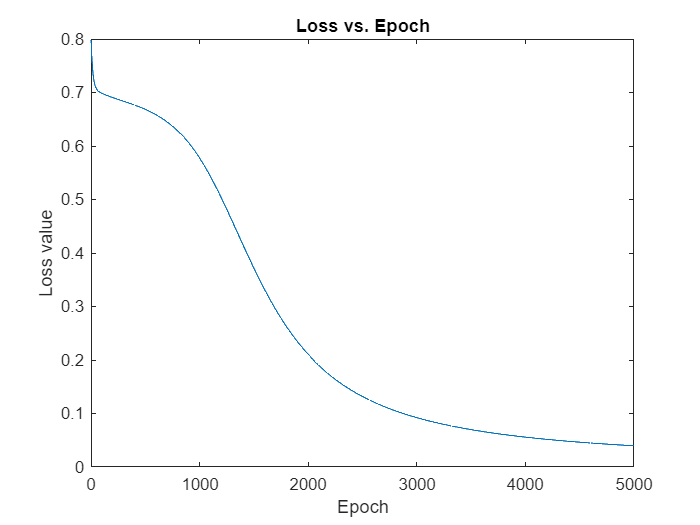

% save the weights before running the next section
w1_saved = w1;
w2_saved = w2;
b1_saved = b1;
b2_saved = b2;
plot(loss_hist(2:end))
title('Loss vs. Epoch')
xlabel('Epoch')
ylabel('Loss value')

In order to check that high learning rates can cause instability we will run the same exact code with an absurdly high learning rate:

learning_rate = 20;
num_epochs = 5000;
disp('Starting weights and biases');

Starting weights and biases


w1 = normrnd(0, 1, [2, 2])

w1 =    -0.0023   -1.0899
   -0.1583   -0.5541


w2 = normrnd(0, 1, [2, 1])

w2 =     0.7010
    1.0955


b1 = normrnd(0, 1, [2, 1])

b1 =     0.1461
    0.3639


b2 = normrnd(0, 1, [1, 1])

b2 = 0.5577

y1 = zeros([2, 1]);
y2 = zeros([1, 1]);
loss_hist = [inf];
num_samples = size(train_input, 1);
for i=1:num_epochs
    w1_grads = zeros([2, 2]);
    w2_grads = zeros([2, 1]);
    b1_grads = zeros([2, 1]);
    b2_grads = zeros([1, 1]);
    loss = 0;
    for j=1:num_samples
        x = train_input(j,:)';
        y = train_output(j);
        y1 = logsig(w1'*x + b1);
        y2 = logsig(w2'*y1 + b2);
        loss = loss - (y*log(y2) + (1-y)*log(1-y2));
        sens_2 = y2 - y;
        w2_grads = w2_grads + sens_2*y1;
        b2_grads = b2_grads + sens_2;
        sens_1 = w2.*(y1.*(1-y1));
        w1_grads = w1_grads + sens_2*sens_1*x';
        b1_grads = b1_grads + sens_2*sens_1;
    end
    w1 = w1 - learning_rate * w1_grads / num_samples;
    w2 = w2 - learning_rate * w2_grads / num_samples;
    b1 = b1 - learning_rate * b1_grads / num_samples;
    b2 = b2 - learning_rate * b2_grads / num_samples;
    loss_hist = [loss_hist; loss/num_samples];
    if mod(i,100) == 0
        fprintf('Loss at the end of epoch %d: %f\n', i, loss_hist(end));
    end
end

Loss at the end of epoch 100: 0.882057
Loss at the end of epoch 200: 0.516814
Loss at the end of epoch 300: 0.801665
Loss at the end of epoch 400: 0.499867
Loss at the end of epoch 500: 0.535955
Loss at the end of epoch 600: 0.605328
Loss at the end of epoch 700: 0.515719
Loss at the end of epoch 800: 0.695992
Loss at the end of epoch 900: 0.474444
Loss at the end of epoch 1000: 0.527139
Loss at the end of epoch 1100: 0.524663
Loss at the end of epoch 1200: 0.523863
Loss at the end of epoch 1300: 0.523465
Loss at the end of epoch 1400: 0.523226
Loss at the end of epoch 1500: 0.523068
Loss at the end of epoch 1600: 0.522955
Loss at the end of epoch 1700: 0.522873
Loss at the end of epoch 1800: 0.522811
Loss at the end of epoch 1900: 0.522765
Loss at the end of epoch 2000: 0.522729
Loss at the end of epoch 2100: 0.522702
Loss at the end of epoch 2200: 0.522683
Loss at the end of epoch 2300: 0.522668
Loss at the end of epoch 2400: 0.522658
Loss at the end of epoch 2500: 0.522651
Loss at t

disp('Final weights and biases');

Final weights and biases


w1

w1 =   -32.0376    9.4829
  -39.9851  -16.7489


w2

w2 =   -14.3157
   11.6025


b1

b1 =    15.1693
   -4.5172


b2

b2 = 1.7779

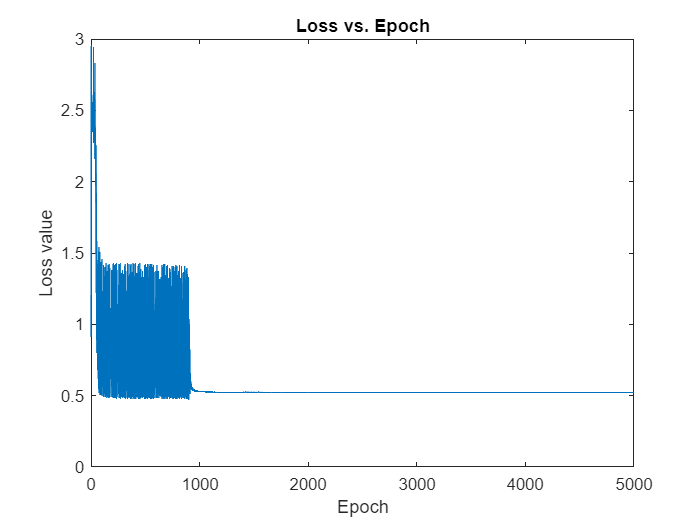

plot(loss_hist(2:end))
title('Loss vs. Epoch')
xlabel('Epoch')
ylabel('Loss value')

We can visually verify from the figure above that the changes in loss values are clearly experiencing heavy instability issues due to very high learning rate.

Finally we will evaluate our trained weights using the test data that we generated in the first section.

Before we run the test samples through the network we can take a look at their distribution first:

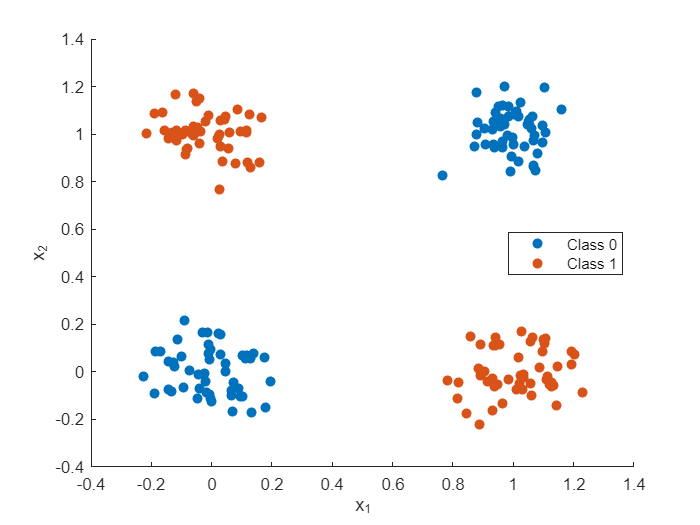

scatter(c1_test(:,1), c1_test(:,2), 'filled')
hold on
scatter(c2_test(:,1), c2_test(:,2), 'filled')
hold on
xlabel('x_1')
ylabel('x_2')
legend('Class 0', 'Class 1', 'Location','best')
hold off

misclassifications = 0;
for i=1:size(test_input, 1)
    %forward
    x = test_input(i,:)';
    y = test_output(i);
    y1 = logsig(w1_saved'*x + b1_saved);
    y2 = logsig(w2_saved'*y1 + b2_saved);
    % y_pred = 1 if y2 >= 0.5 and 0 otherwise
    y_pred = double(y2>=0.5);
    if y_pred ~= y
        misclassifications = misclassifications + 1;
    end
end
error_rate = misclassifications/size(test_input, 1)

error_rate = 0

As we can see, the network has managed to perfectly classify the entire test data.